clc; clear all; close all;

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


A = [0 1; -1 -2]; 
B=[0 1]'; 
C=[1 0]; 
D = [0]

D = 0


P2 = tf(ss(A,B,C,D))

P2 =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


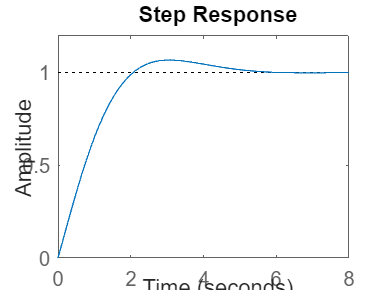

C2=pidtune(P2,'PID');
%cerramos lazo
PCL2=feedback(P2*C2,1);
step(PCL2)


P1 = 1/(s+3);
POL1 = P1*PCL2

POL1 =
 
         0.6997 s^2 + 2.046 s + 1.454
  -------------------------------------------
  s^4 + 5.7 s^3 + 11.14 s^2 + 10.59 s + 4.362
 
Continuous-time transfer function.
Model Properties




Gss=ss(POL1)

Gss =
 
  A = 
            x1       x2       x3       x4
   x1     -5.7   -2.786   -1.324  -0.5452
   x2        4        0        0        0
   x3        0        2        0        0
   x4        0        0        1        0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
 
  C = 
           x1      x2      x3      x4
   y1       0  0.1749  0.2557  0.1817
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Qy=100;
Q_ext=Gss.C'*Qy*Gss.C;
R_ext=0.01;

K_ext=lqr(Gss.A,Gss.B,Q_ext,R_ext)

K_ext =     9.2892   24.0224   27.3752   17.6377


Kr_ext=(-(Gss.C-Gss.D*K_ext)*(Gss.A-Gss.B*K_ext)^-1*Gss.B+Gss.D)^-1;

ACL1=Gss.A-Gss.B*K_ext;
BCL1=Gss.B*Kr_ext;
CCL1=Gss.C-Gss.D*K_ext;
DCL1=Gss.D*Kr_ext;

Gss=ss(ACL1,BCL1,CCL1,DCL1);
pole(Gss)

ans =   -6.0306 + 5.7855i
  -6.0306 - 5.7855i
  -1.7090 + 0.0000i
  -1.2188 + 0.0000i


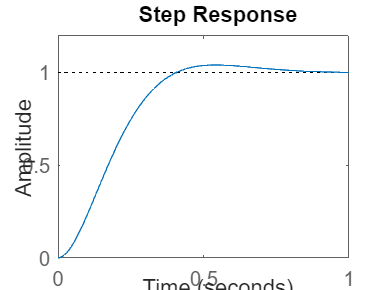

step(Gss)